# Author: Lu, Chia-Feng 2013.11.29

clear, close all
clc

## initialize parameters

path(path,'.\fastica_25');  % add FastICA path

samplerate = 2000; % in Hz

ICNo=3;  % the specified number of independent components
PCNo=4;  % the preserved number of PCs

## load data

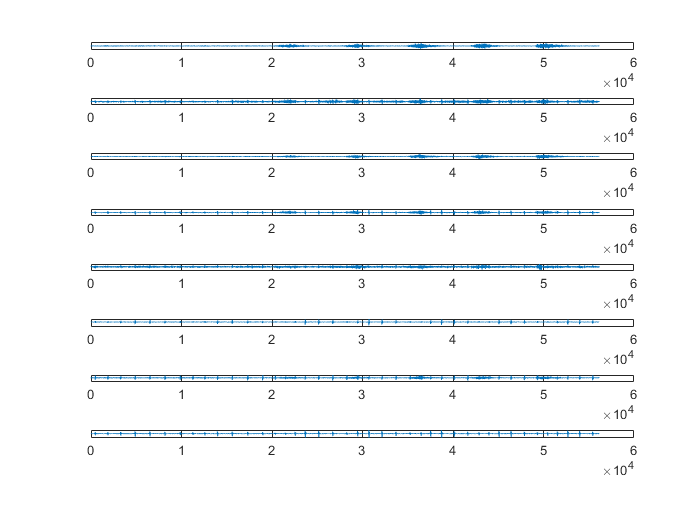

load('EMGdata.mat')

figure,
for i=1:size(EMGdata,2)
    subplot(size(EMGdata,2),1,i),plot(EMGdata(:,i))
end

## perform FastICA

[icasig, A, W] = fastica(EMGdata','numOfIC',ICNo,'displayMode','off','firstEig',1,'lastEig',PCNo); % fast ICA

Number of signals: 8
Number of samples: 56158
Calculating covariance...
Reducing dimension...
Selected [ 4 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 0.00184768 ]
Largest remaining (non-zero) eigenvalue [ 0.0215198 ]
Sum of removed eigenvalues [ 0.0029443 ]
[ 92.8207 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 1.44329e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .......computed ( 7 steps ) 
IC 2 ............................computed ( 28 steps ) 
IC 3 .........computed ( 9 steps ) 
Done.
Adding the mean back to the data.


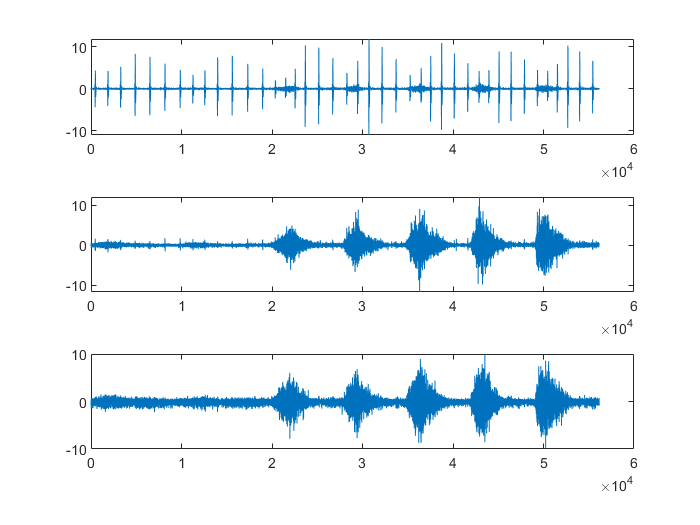


% [icasig, A, W] = fastica(EMGdata','numOfIC',ICNo,'displayMode','off','interactivePCA','on'); % fast ICA
% fasticag(EMGdata')

figure,
for i=1:size(icasig,1)
    subplot(size(icasig,1),1,i),plot(icasig(i,:))
end


return

## remove ICs dominated by cardiac signal and noise

rejectICA=[1];

A2=A;
icasig2=icasig;

## reconstruct the signal

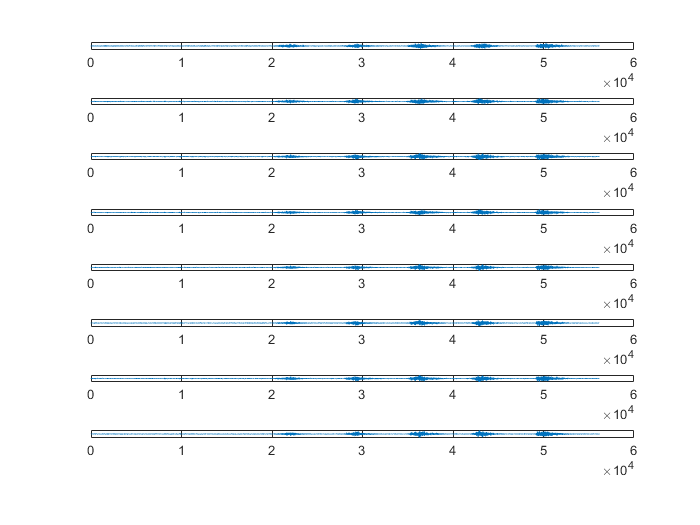

A2(:,rejectICA)=[];
icasig2(rejectICA,:)=[];

newEMGdata=(A2*icasig2)';

figure,
for i=1:size(newEMGdata,2)
    subplot(size(newEMGdata,2),1,i),plot(newEMGdata(:,i))
end